# 清空数据

clc 
clear

## 初始化网格

global Nx Ny; %#ok<GVMIS>
Nx = 3; Ny = 3;
mesh = ConstuctMesh([Nx,Ny],[1,1]);

## 初始化物理参数

k = 10;

## 初始化物理场

T = generatefield(mesh,fieldDimension.vol,fieldType.scalar);

## 物理场赋值

T = initialFieldValue(T,0);

## 初始化边界条件

T = setBoundaryCondition(T,1,BCType.Dirichlet,BCSelect.w);
T = setBoundaryCondition(T,0,BCType.Neumann,BCSelect.e);
T = setBoundaryCondition(T,0,BCType.Dirichlet,BCSelect.s);
T = setBoundaryCondition(T,0,BCType.Neumann,BCSelect.n);

## 初始算子

lap_T = laplace_fvm(mesh,k,laplaceScheme.Gauss,T);

## 矩阵组装和求解

[Matrix_T,T] = matrixSystem(T,lap_T,'+',IS.solve);

## 后处理

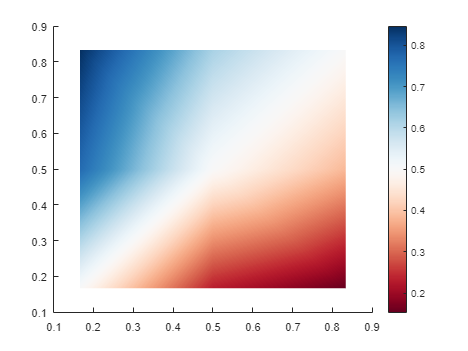

RESULT = outputField(mesh,outputSelect.smooth,color.RdBu11,T);